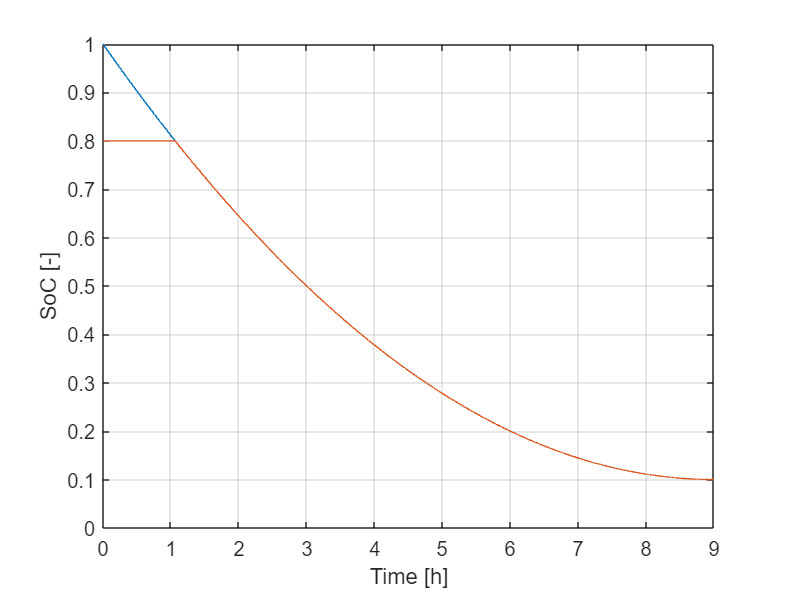

clear;
close all;

c = 1;
xEnd = 9*3600;
yEnd = 0.1;
yEndConsumed = 1 - 2*yEnd;
b = (2*yEnd - 2*c) / xEnd;
a = (yEnd - c - b*xEnd) / xEnd^2;

t = linspace(0,xEnd,10000);
SoC = a*t.^2 + b*t + c;
horizon = SoC >= yEndConsumed;
SoC02 = SoC .* ~horizon + yEndConsumed .* horizon;

plot(t / 3600, SoC)
hold on
plot(t/3600, SoC02)
ylim([0, 1])
xlim([0, xEnd / 3600])
xlabel("Time [h]")
ylabel("SoC [-]")
grid on
box on